# `Markov Chains and The Lake Model`

## `Learning Goals`

- `Understand the construction of a Markov process`

- `Experiment with the steady state of a Markov process`

- `Explore the Lake Model as an application of Markov chains`

## `Relevant Linear Algebra Concepts`

- `Markov chains`

- `Normed Vector Spaces`

- `Eigenvalues`

- `Matrix and vector operations`

## `Predicting Future Employment `

`Suppose you are currently employed, what is the likelihood you will be employed next month or the month after that? What is your chance of employment in the long run? When asking questions about future employment, or the future in general, economists turn to the predictive power of Markov chains for key insights.`

## `I. Markov Chains `

### `Origin of Markov Chains: `

### `Definitions:`

`A Markov Chain is a process in which the probability of the system being in a particular state at a given observational period depends only on its state at the immediately preceding observational period (Kolman and Hill 483). `

`We can define a single state change with the function `${\phi :\mathbb{R}}^n \longrightarrow {\mathbb{R}}^n$` given by `$x\mapsto \textrm{Px}$` where `$P=\left\lbrack p_{\textrm{ij}} \right\rbrack$` is called the transition matrix or Markov matrix. A transition matrix holds the probabilities of moving from one state to another over the course of a single period. Hence, in a system with n states, the transition matrix will be of size n by n. Using column vector convention, the columns of the transition matrix must sum to 1. `

`Moreover, `

$x^k =\left\lbrack \begin{array}{c}
p_1^k \\
\vdots \\
p_n^k 
\end{array}\right\rbrack \;\;$ `where `$k\ge 0,\;j=1\cdots n,$

`is called the state vector of the Markov process in the observational period k, where `$p_j^k$` is the probability that the system is in state j during the observational period k. Hence, `$x^0$` is the initial state vector and `$x^{k+1}$` is given by `$Px^k$`. More generally, `$x^k =P^k x^0$`. `

### `Equilibrium:`

`As the number of times a transition matrix is applied to the initial state vector increases, for certain Markov matrices, the probabilities held in the state vector converge to fixed values. This fixed vector is called the steady state vector, and the Markov process is said to be in equilibrium. Once a Markov process is in equilibrium, the following is true,`

$x^{k+1} =x^k$.

`Use the following tool to see how the probabilities held in the state vector converge over many observational periods.`

`To simplify this visualization, a given vector is represented by a real number called a norm. Here, norms are defined to be the squared Euclidean norm of a vector.`

`Change x to change the number of passing observational periods. Watch how the norms of the state vectors converge as `$x\longrightarrow \infty$`. Feel free to modify the values held in A to see how this changes convergence. What happens if a zero is inserted into A?`

x = 8;

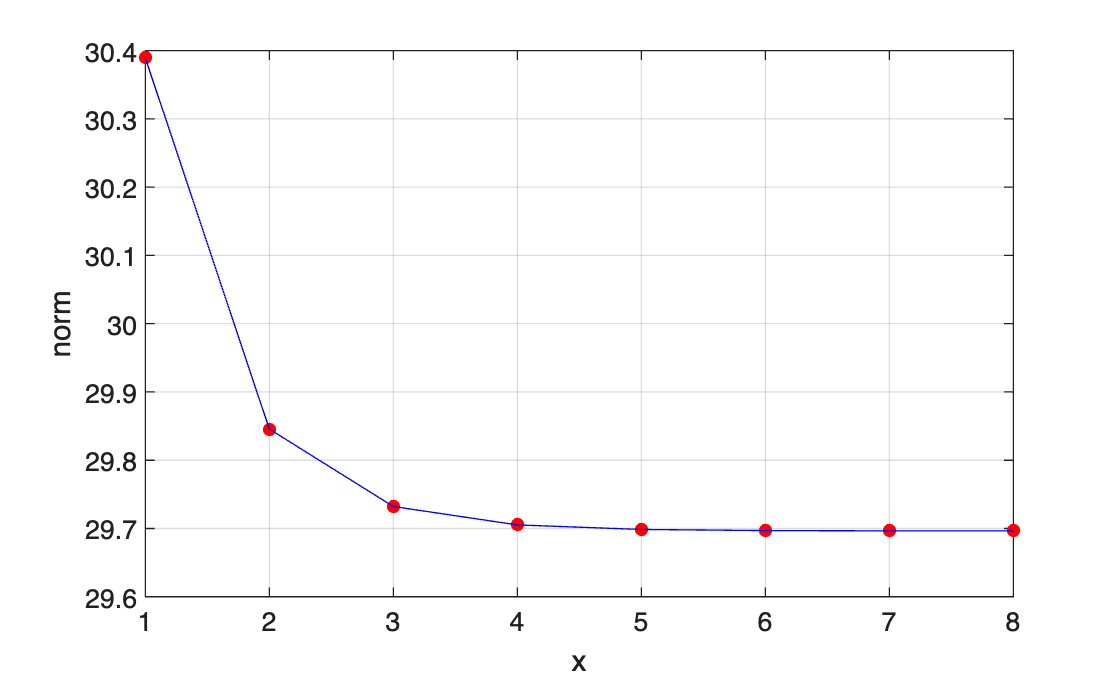

%Transition Matrix
A = [0.68 0.32; 0.43 0.57];
%Initial State Vector
y = [3; 5];

dot_vals = zeros(1, x);

for n = 1:x
    result = (A^n) * y;
    dot_vals(n) = dot(result, result);
end

plot(1:x, dot_vals,'r.',MarkerSize=15)
hold on 
plot(1:x, dot_vals,'b')
grid on
xlabel('x')
ylabel('norm')

## `II. Mass Transit Example (Kolman and Hill 488)`

`Suppose a new mass transit system has just gone into operation. The transit authority has conducted studies that predict the percentage of commuters who will change to mass transit (M) or continue driving their automobiles (A). The following transition matrix shows the results:`

`Further suppose the population of the area remains constant, and that intially 30% of commuters use mass transit and 70% use their automobiles.`

`(a) What is the percentage of commuters who will use the mass transit system after 1 year? After 2 years? `

%Let our initial state vector and transition matrix be the following,
v=[30; 70];
M=[0.7, 0.2; 0.3, 0.8];
%Apply the transition matrix once to find v after one year has passed.
v1 = M*v

v1 =     35
    65


`Hence after one year 35% of commuters use mass transit. `

%Apply the transition matrix once more to find v after two years have passed.
v2= M*v1

v2 =    37.5000
   62.5000


`After 2 years 37.50% of commuters use mass transit. `

`(b) What percentage of commuters will use the mass transit system in the long run?`

`The following lines of code will determine the long-run equilibrium using a eigenvalue centered method. To do this by hand, call upon the fact that the Markov process is in equilibrium when `$v^{k+1} =v^k$`. Solving this analytically will give you your steady-state vector.`

[V, D] = eig(M);

% Find the eigenvalue equal to 1
idx = find(abs(diag(D) - 1) < 1e-8);

v = V(:, idx);

% Normalize so entries sum to 1
v_steady_state = v / sum(v)

v_steady_state =     0.4000
    0.6000


## `III. The Lake Model (two-state Markov process)`

`The following section reviews the construction and applications, both practical and conceptial, of the Lake Model. The Lake Model is a way of modeling employment flows that provides the user with a method of better understanding future unemployment.`

`In an economy, the labor force is composed of two collectively exhaustive groups: those who are employed (e) and those who are unemployed (u). Hence, if you are a member of the labor force, there exists some probability that you are unemployed and some probability that you are employed. Moreover, in a Markov model with states employed and unemployed there are two distinct flows between these two states: the job-separation rate `$\left(\alpha \right)$` and the job-finding rate `$\left(\lambda \right)$`. The job-separation rate is the probability that an employed person loses their job and flows from employed to unemployed. The job-finding rate is, not surprisingly, the probability that an unemployed person will find a job and flow from unemployed to employed. Furthermore, someone who is employed can stay employed, and someone who is unemployed can stay unemployed; we must include these flows as well. The Lake Model is a Markov model characterizing these gross flows of employment and unemployment and is depicted in Figure 1.`

#### Figure 1:

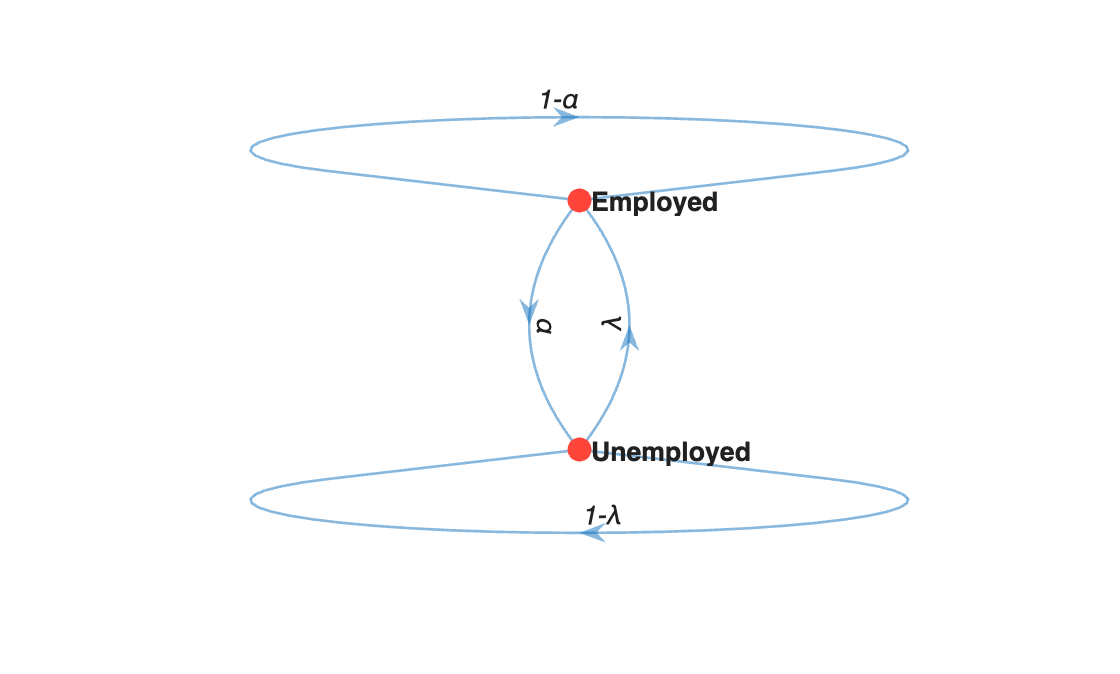

### `Individual Dynamics in the Lake Model`

`Let ``e`` be the probability of being employed in a given observational period and let `$1-e$` be the probability of being unemployed during this same period. This gives the following state vector,`

$x=\left\lbrack \begin{array}{c}
e\\
1-e
\end{array}\right\rbrack$`.`

`Moreover, let the job-finding rate be given by ``λ`` and let the job-separation rate be given by ``α``. This yields the following transition matrix based on Figure 1,`

$P=\left\lbrack \begin{array}{cc}
1-\alpha  & \lambda \\
\alpha  & 1-\lambda 
\end{array}\right\rbrack$.

#### `Example:  `

`Say `$\alpha =3\ldotp 2\;\;\textrm{and}\;\lambda =3\ldotp 3$`. These are the latest numbers as of January 2026 from the Bureau of Labor Statistics. Hence,  `

P=[1-0.32, 0.33; 0.32, 1-0.33];

`Now, suppose you, and many others, believe that your current employment is decided by the flip of a coin, as the half the people in the labor force are unemployed. This suggests that the probability a random individual being employed or unemployed is represented by the following:`

x0=[0.5;0.5];

`Now, suppose each month is an observational period. Using our Markov process, you can calculate the probability you are employed one month later.`

% Update the state vector using the transition matrix
x1 = P *x0

x1 =     0.5050
    0.4950


`Hence, after one month, your chance of employment given the current exogenous economic variables (`$\alpha$ and $\lambda$`) has increased from 50% to 50.5%.`

`Now let's see what your chance of employment is in a year, or 12 observational periods.`

% Update the state vector using the transition matrix
X12 = P^12 * x0

X12 =     0.5077
    0.4923


`Fantastic, after a year, your likelihood of employment has increased by 0.7%. However, what is really happening is over the course of the year the Markov process converges to its steady state, which is approximated by X12. The following heatmap is a visualization of how your odds of employment and unemployment are changing and converging to an equilibrium probability distribution as the number of observational periods increases. `

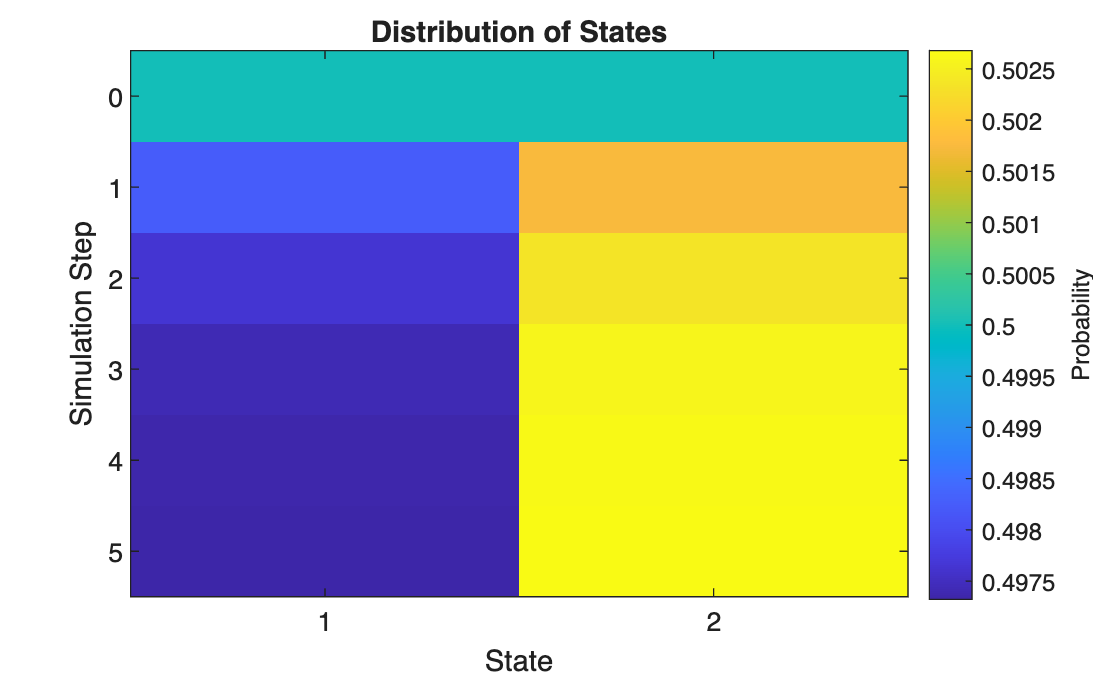

### `The Lake Model and Estimating Unemployment`

`How can we estimate unemployment with the Lake Model? Well, we simply apply the same process from the prior example to the bare Markov matrix and initial state vector given by the Lake Models construction and what we are left with are forms to estimate the employment and unemployment rates using just our job-separation and job-finding rates. `

`Compute the following matrix multiplication,`

$\left\lbrack \begin{array}{cc}
1-\alpha  & \lambda \\
\alpha  & 1-\lambda 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
e\\
1-e
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(1-\alpha \right)e+\left(1-e\right)\lambda \\
\alpha e+\left(1-\lambda \right)\left(1-e\right)
\end{array}\right\rbrack$    (1)

`Hence, the likelihood of employment is given by,`


$$e=\left(1-\alpha \right)e+\left(1-e\right)\lambda =e-\alpha e+\lambda -\lambda e$$



$$\Longrightarrow e-e+\alpha e+\lambda e=\lambda$$



$$\Longrightarrow e\left(\alpha +\lambda \right)=\lambda$$



$$\Longrightarrow e=\frac{\lambda }{\alpha +\lambda }$$


`Moreover, the unemployment rate is given by,`


$$1-e=1-\frac{\lambda }{\alpha +\lambda }$$


`This technique for predicting unemployment supplies the user with a fundamental understanding of how employment flows impact the unemployment rate, however, it does not accurately estimate the unemployment rate in the real world. The reason why is simply that several assumptions were implicitly made when we began exploring the Lake Model that don't necessarily hold in the real world. For example, we assumed the size of the labor force is constant, as we did not consider flows from employment or unemployment to a third group of people not in the labor force. For example, many people are hired for jobs who, beforehand, did not consider themselves unemployed. For this reason, the above formula may overestimate unemployment.`

### `The Long-run Steady State in the Lake Model`

`How do we find the equilibrium of the Lake Model? Remember, whenever a Markov process is in equilibrium, the following is true: `$x^{k+1} =x^k$`. Hence, the Lake Model has reached its steady state whenever the unemployment and employment rates observed in one period are equal to those observed in the next. We call `$u^*$` the steady-state unemployment rate, or to use more exact economic terminology, the natural unemployment rate; thus, it is the case that `$u^{k+1} =u^k =u^*$`. `

`Taking the result labeled (1) from the prior section, `


$$u^{k+1} =\alpha e+\left(1-\lambda \right)\left(1-e\right)$$


`Extending this,`


$${\Longrightarrow u}^* =\alpha e+\left(1-\lambda \right)u^*$$



$${\Longrightarrow u}^* =\alpha e+u^* -\lambda u^*$$



$$\Longrightarrow \left(u^* -u^* \right)+\lambda u^* =\alpha e$$



$$\Longrightarrow \lambda u^* =\alpha e$$
      

`Finally we come to, `

$u^{k+1} =u^k \iff \lambda u^* =\alpha e$  (2)

`The equation labeled (2) is the key insight of the Lake Model. What (2) suggests is whenever the Lake Model is in equilibrium, the flows in and out of unemployment are equal. In other words, when the economy is at the steady-state level of unemployment, the number of people finding jobs equals the number of people losing jobs. In the space of macroeconomics, this gives a conceptual baseline from which determinations about the current level of unemployment can be made. For example, if `$u>u^* ,$` where `$u$ `is the current observed unemployment rate, the statement that the economy is above the equilibrium level and, in the long run, unemployment levels will decrease is a fair conclusion extending from the results of the Lake Model.`

## `Conclusion:`

`The Markov chain is an essential tool in the toolboxes of both mathematicians and economists. The Markov process construction allows for complex, dynamic systems to be more effectively modeled, offering the ability to predict the future based on the present. In this module, a Markov process was used to unearth some central macroeconomic mechanics of unemployment, but it is not difficult to see Markov chains have many more applications. From predicting future stock prices to analyzing population demographics, Markov chains work their way into our lives, helping us to predict the future.`

## `References:`

`Kolman, Bernard, and David A Hill. ``Elementary Linear Algebra with Applications``. Pearson Higher Ed, 29 Aug. 2013.`

`“Markov Chains — Econ 303a: Advanced Macroeconomics I.” ``Brandeis.edu``, 2015, people.brandeis.edu/~ghall/econ303/build/html/markov_chains.html.`

`U.S. Bureau of Labor Statistics. “U.S. Bureau of Labor Statistics.” ``Bls.gov``, U.S. Bureau of Labor Statistics, 29 Aug. 2024, `[`www.bls.gov/.`](http://www.bls.gov)

`Veritasium. “The Strange Math That Predicts (Almost) Anything.” ``YouTube``, 25 July 2025, www.youtube.com/watch?v=KZeIEiBrT_w. Accessed 1 Aug. 2025.`